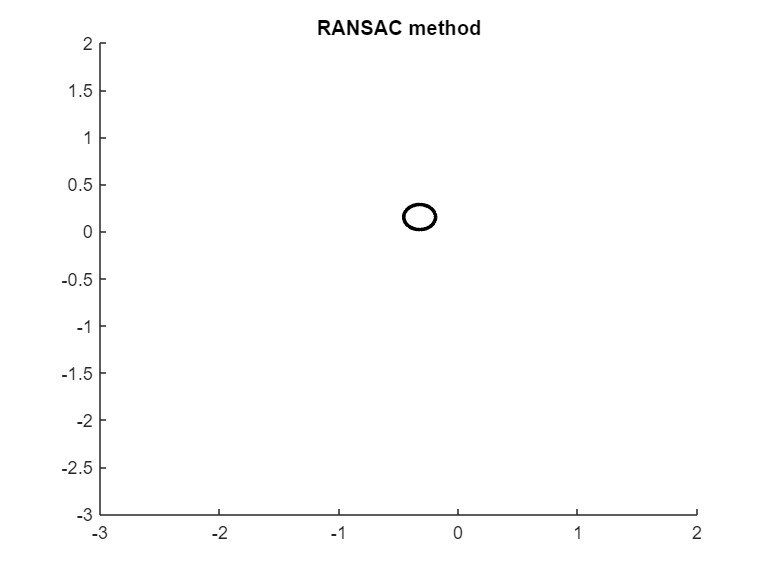

load playpensample.mat
index=find(r~=0);
r_clean=r(index);
theta_clean=theta(index);
figure;
[x,y]=pol2cart(deg2rad(theta_clean),r_clean);

figure;
clf
hold on
%scatter(x,y,20'.', "filled")


k_rad = 0.1329;
 [center, inliers, outliers] = ransac_circ(x, y, k_rad);


[X, Y, Z, dx, dy] = make_potential_field(x, y, inliers, outliers);

[dx, dy] = gradient(Z, 0.2);

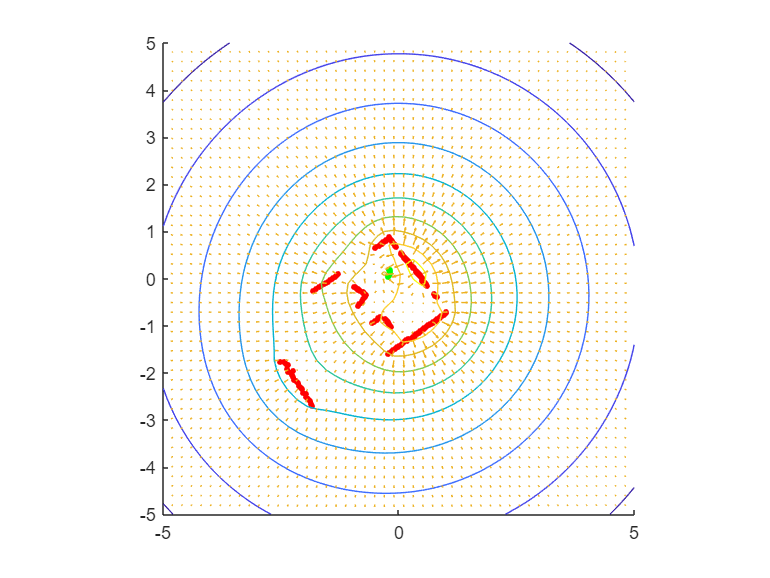

clf
hold on

scatter(inliers(:,1),inliers(:,2),10, "green", "filled")
scatter(outliers(:,1), outliers(:,2), 10, "red", "filled")
contour(X, Y, real(Z))
quiver(X(:), Y(:), -1*dx(:), -1*dy(:))
axis equal
axis([-5 5 -5 5])



%  for i = 1:length(X)
%         for j = 1:length(Y)
%             quiver(X(i, j), Y(i, j), dx(i, j), dy(i, j))
%       
%         end
%  end


% t = linspace(0,2*pi,100);
% circ_x = k_rad * cos(t) + xc;
% circ_y = k_rad * sin(t) + yc;
% plot(circ_x, circ_y, "linewidth", 2)